%Question 1 example & plot
clear all
syms x

%function to be expanded
f(x) = sin(x);

%taylor series expansion of f(x)
g(x) = taylor(f,x,0,"Order",6)

$$g(x) = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

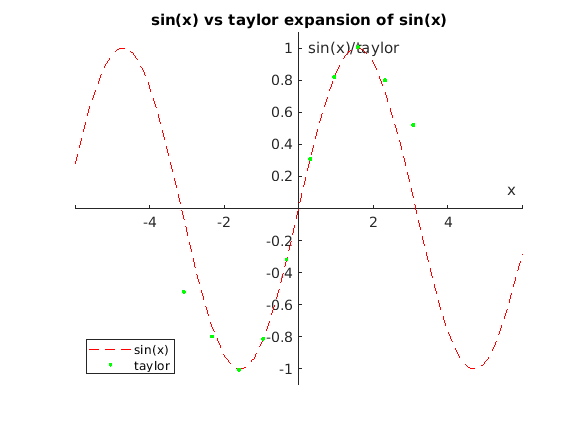



fplot(f,"--r") %plotting sine function

%setting plot limits
xlim([-6 6])
ylim([-1.1 1.1])

%beautifying plot
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

hold on %plotting on same graph

%plotting Maclauren series
fplot(g,".g")

%labelling plot
xlabel("x")
ylabel("sin(x)/taylor")
title("sin(x) vs taylor expansion of sin(x)")
legend("sin(x)","taylor","location","southwest")

hold off %ending plotting


%calculating sin(x)
sin(0.3)

ans = 0.2955


%comparing with Maclauren series
g(0.3)

$$ans = \frac{1182081}{4000000}$$

eval(ans)

ans = 0.2955

%checking answers to question 1
clear all

syms x

%declaring function to be expanded
f(x) = sin(4*x);

%creating expansion
g(x) = taylor(f,x,0,"Order",6)

$$g(x) = \frac{128\,x^{5}}{15}-\frac{32\,x^{3}}{3}+4\,x$$

%question 2
clear all

syms x

%declaring function to be expanded
f(x) = cos(x - pi/3);

%calculating expansion
g(x) = taylor(f,x,pi/3,"Order",7)

$$g(x) = \frac{{\left(x-\frac{\pi }{3}\right)}^{4}}{24}-\frac{{\left(x-\frac{\pi }{3}\right)}^{2}}{2}-\frac{{\left(x-\frac{\pi }{3}\right)}^{6}}{720}+1$$


%declaring my pen and paper answer
b = x-pi/3;
g_ans(x) = 1 - (b^2)/2 + (b^4)/factorial(4) - (b^6)/factorial(6);

%checking answers match (wasn't actually required as they are identical!)
simplify(g(x)-g_ans(x))

$$ans = 0$$

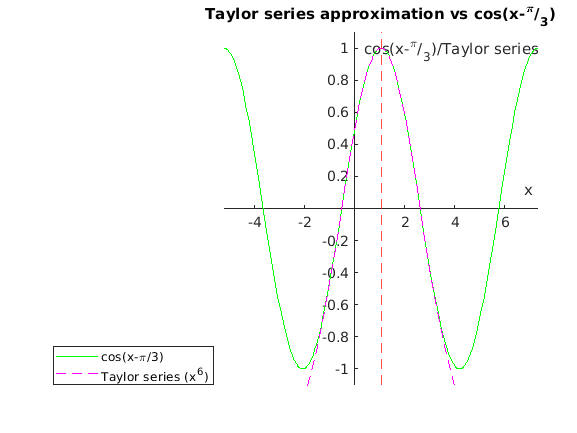


%plotting cosine function centereed on pi/3
fplot(f(x),"-g")
xlim([(pi/3)-2*pi (pi/3)+2*pi])
ylim([-1.1 1.1])

hold on %plotting on same graph

%plotting taylor series
fplot(g(x),"--m")

xline(pi/3,"--r") %x line about wher expansion is performed.

hold off %end plotting

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("x");
ylabel("cos(x-^{\pi}/_{3})/Taylor series");
title("Taylor series approximation vs cos(x-^{\pi}/_{3})")
legend("cos(x-\pi/3)","Taylor series (x^{6})","Location","southwestoutside")

%question 3
clear all
syms x %declaring symbolic variables

%declaring function to be expanded
f(x) = log(1+x)

$$f(x) = \log\left(x+1\right)$$


%calculating expansion
g5(x) = taylor(f,x,0,"Order",5)

$$g5(x) = -\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

g20(x) = taylor(f,x,0,"Order",20)

$$g20(x) = \frac{x^{19}}{19}-\frac{x^{18}}{18}+\frac{x^{17}}{17}-\frac{x^{16}}{16}+\frac{x^{15}}{15}-\frac{x^{14}}{14}+\frac{x^{13}}{13}-\frac{x^{12}}{12}+\frac{x^{11}}{11}-\frac{x^{10}}{10}+\frac{x^{9}}{9}-\frac{x^{8}}{8}+\frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

g50(x) = taylor(f,x,0,"Order",50)

$$g50(x) = \frac{x^{49}}{49}-\frac{x^{48}}{48}+\frac{x^{47}}{47}-\frac{x^{46}}{46}+\frac{x^{45}}{45}-\frac{x^{44}}{44}+\frac{x^{43}}{43}-\frac{x^{42}}{42}+\frac{x^{41}}{41}-\frac{x^{40}}{40}+\frac{x^{39}}{39}-\frac{x^{38}}{38}+\frac{x^{37}}{37}-\frac{x^{36}}{36}+\frac{x^{35}}{35}-\frac{x^{34}}{34}+\frac{x^{33}}{33}-\frac{x^{32}}{32}+\frac{x^{31}}{31}-\frac{x^{30}}{30}+\frac{x^{29}}{29}-\frac{x^{28}}{28}+\frac{x^{27}}{27}-\frac{x^{26}}{26}+\frac{x^{25}}{25}-\frac{x^{24}}{24}+\frac{x^{23}}{23}-\frac{x^{22}}{22}+\frac{x^{21}}{21}-\frac{x^{20}}{20}+\frac{x^{19}}{19}-\frac{x^{18}}{18}+\frac{x^{17}}{17}-\frac{x^{16}}{16}+\frac{x^{15}}{15}-\frac{x^{14}}{14}+\frac{x^{13}}{13}-\frac{x^{12}}{12}+\frac{x^{11}}{11}-\frac{x^{10}}{10}+\frac{x^{9}}{9}-\frac{x^{8}}{8}+\frac{x^{7}}{7}-\frac{x^{6}}{6}+\frac{x^{5}}{5}-\frac{x^{4}}{4}+\frac{x^{3}}{3}-\frac{x^{2}}{2}+x$$

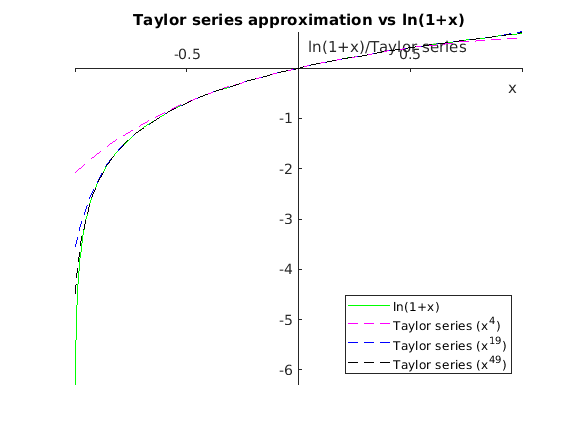


%plotting log function 
fplot(f(x),"-g")
xlim([-1 1])
%ylim([-1.1 1.1])

hold on %plotting on same graph

%plotting taylor series
fplot(g5(x),"--m")
fplot(g20(x),"--b")
fplot(g50(x),"--k")

hold off %end plotting

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off;

%labelling graph
xlabel("x");
ylabel("ln(1+x)/Taylor series");
title("Taylor series approximation vs ln(1+x)")
legend("ln(1+x)","Taylor series (x^{4})","Taylor series (x^{19})","Taylor series (x^{49})","Location","southeast")